Práctica 4: filtros digitales IIR  

1. Diseño de filtros IIR

a) b) c) d) Se crean 4 filtros con fdatool

2. Análisis de filtros

2.1. Módulo y fase

a) Respuesta en Magnitud (dB vs Hz)

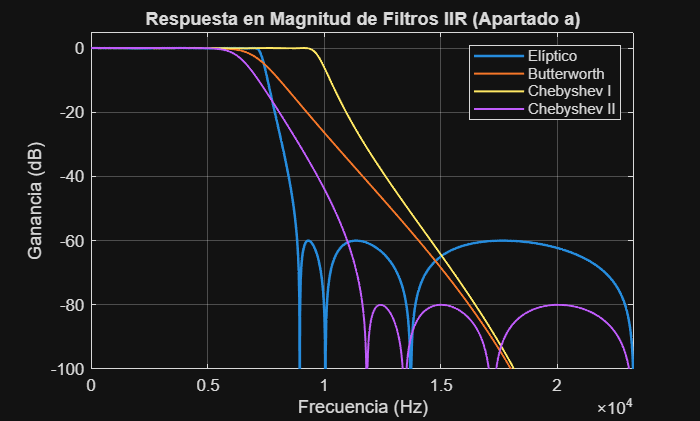

% Obtenemos la respuesta en frecuencia de los cuatro filtros diseñados
N_puntos = 50000; % Usamos N_puntos (50 000) y la frecuencia de muestreo Fs

[Hb, f_vec] = freqz(Num_b, Den_b, N_puntos, Fs);      % Butterworth
[HcI, ~]    = freqz(Num_c_I, Den_c_I, N_puntos, Fs);  % Chebyshev I
[HcII, ~]   = freqz(Num_CII, Den_CII, N_puntos, Fs);  % Chebyshev II
[He, ~]     = freqz(Num_e, Den_e, N_puntos, Fs);      % Elíptico

% Representación de la Magnitud en dB
figure;
plot(f_vec, 20*log10(abs(He)), 'LineWidth', 1.5); hold on;
plot(f_vec, 20*log10(abs(Hb)), 'LineWidth', 1.2);
plot(f_vec, 20*log10(abs(HcI)), 'LineWidth', 1.2);
plot(f_vec, 20*log10(abs(HcII)), 'LineWidth', 1.2);
grid on;
title('Respuesta en Magnitud de Filtros IIR (Apartado a)');
xlabel('Frecuencia (Hz)');
ylabel('Ganancia (dB)');
legend('Elíptico', 'Butterworth', 'Chebyshev I', 'Chebyshev II');
axis([0 Fs/2 -100 5]); % Ajuste de ejes para ver el detalle del rizado y caída

b) Respuesta en Fase (Radianes vs Hz)

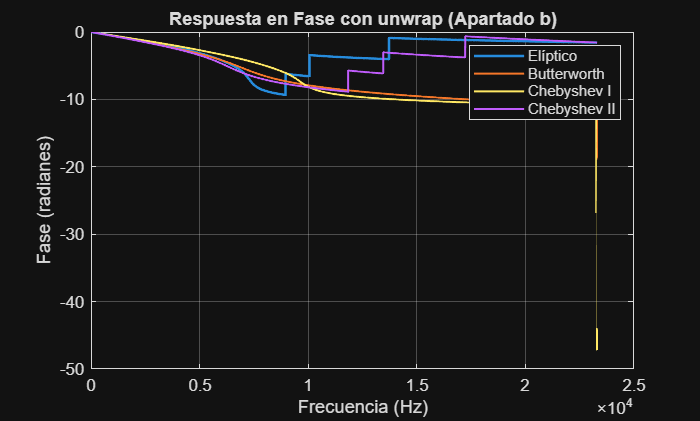

% Se utiliza la función unwrap para eliminar los saltos de fase de ±pi
% Aprovechamos los vectores calculados en la celda anterior

figure;
plot(f_vec, unwrap(angle(He)), 'LineWidth', 1.5); hold on;
plot(f_vec, unwrap(angle(Hb)), 'LineWidth', 1.2);
plot(f_vec, unwrap(angle(HcI)), 'LineWidth', 1.2);
plot(f_vec, unwrap(angle(HcII)), 'LineWidth', 1.2);
grid on;
title('Respuesta en Fase con unwrap (Apartado b)');
xlabel('Frecuencia (Hz)');
ylabel('Fase (radianes)');
legend('Elíptico', 'Butterworth', 'Chebyshev I', 'Chebyshev II');

2.2. Polos y ceros

a) Representación del diagrama de polos y ceros

b) ¿Son estables los filtros? ¿Por qué?

c) Justificación de por qué son paso bajo

d) Justificación matemática de los máximos de oscilación (Filtro Elíptico)

e) Frecuencias eliminadas en el Filtro Elíptico    

% Las frecuencias eliminadas corresponden a los ceros situados sobre el círculo unidad.

% 1. Calculamos las raíces del numerador (ceros) del filtro elíptico
ceros_e = roots(Num_e);

% 2. Obtenemos el ángulo (fase) de los ceros en radianes
angulos_ceros = angle(ceros_e);

% 3. Convertimos los ángulos a frecuencias en Hz: f = (ang * Fs) / (2*pi)
% Filtramos solo los ángulos positivos para no repetir frecuencias simétricas
f_eliminadas = sort(angulos_ceros(angulos_ceros > 0)) * Fs / (2*pi);

% 4. Mostramos los resultados
fprintf('Las frecuencias eliminadas (ceros de transmisión) son:\n');

Las frecuencias eliminadas (ceros de transmisión) son:


for i = 1:length(f_eliminadas)
    fprintf('Frecuencia %d: %.2f Hz\n', i, f_eliminadas(i));
end

Frecuencia 1: 8957.86 Hz
Frecuencia 2: 10057.60 Hz
Frecuencia 3: 13721.17 Hz
Frecuencia 4: 23300.00 Hz


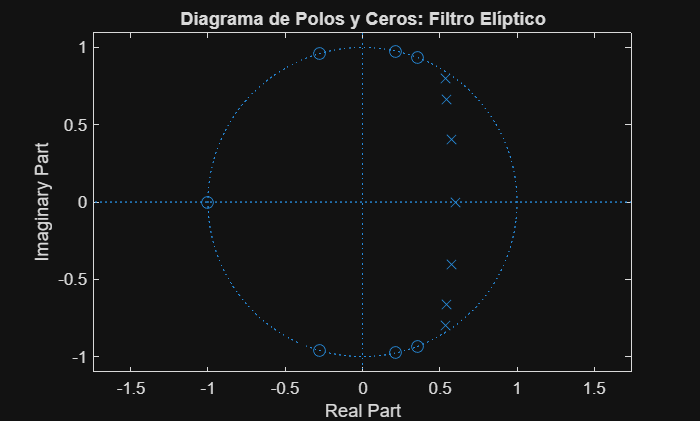


% Visualización para comprobación
figure;
zplane(Num_e, Den_e);
title('Diagrama de Polos y Ceros: Filtro Elíptico');

2.3. Estabilidad

b) Coeficientes del filtro modificado (Factor 0.95)

d) Coeficientes del filtro modificado (Factor 1.05)

f) Efectos en la respuesta en frecuencia

g) Efectos en el diagrama de polos y ceros

h) Efectos en la respuesta impulsional